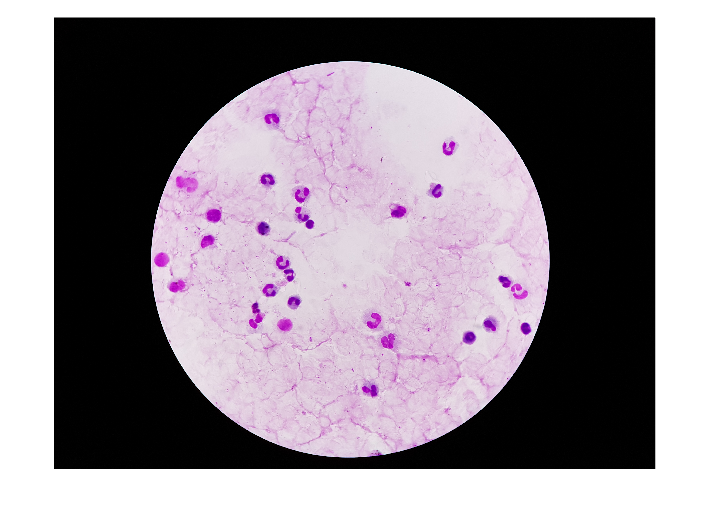

IPF = imread('20170829_174225.jpg');
Imagen_FILT = im2double(IPF);

figure;imshow(Imagen_FILT);

I_gray = rgb2gray(Imagen_FILT);
I_gray_uint8 = im2uint8(I_gray);

% Máscara del campo de visión
Imagen_mascara_gray = rgb2gray(cat(3, IPF(:,:,1), IPF(:,:,2), zeros(size(IPF(:,:,1)))));
fov_mask = segmentCellsStainBased(Imagen_mascara_gray);

% Leer parásitos reales
fileID = fopen('20170829_174225.txt', 'r');
lines = textscan(fileID, '%s', 'Delimiter', '\n'); fclose(fileID); lines = lines{1};
lines(1) = [];
data = cell(length(lines), 7);
for i = 1:length(lines)
    tokens = strsplit(lines{i}, ',');
    for j = 1:7
        if j <= length(tokens)
            data{i, j} = tokens{j};
        else
            data{i, j} = '';
        end
    end
end
dataTable = cell2table(data, 'VariableNames', {'ID','Label','Comment','Shape','NumPoints','X1','Y1'});
dataTable.X1 = str2double(dataTable.X1); dataTable.Y1 = str2double(dataTable.Y1);
solo_parasitos = dataTable(ismember(dataTable.Label, {'Parasite', 'Parasitized'}), :);

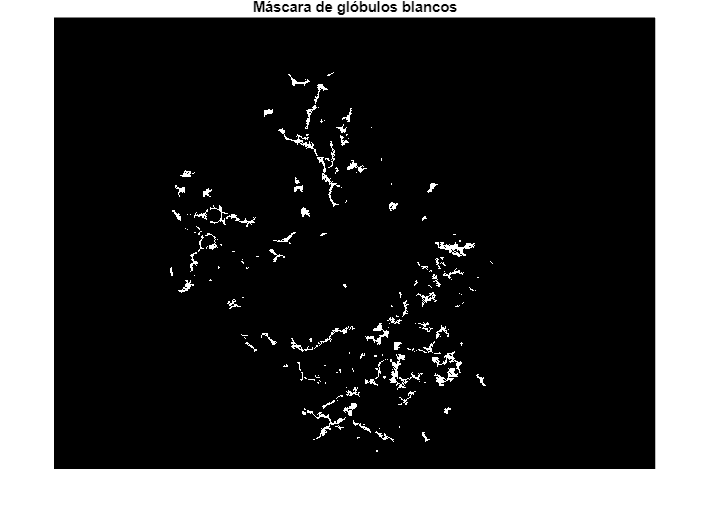

% Segmentación de glóbulos blancos con Region Growing
I_eq = adapthisteq(I_gray);
I_eq(~fov_mask) = 0;
BW_dark = I_eq < 0.4;                    
BW_dark = bwareafilt(BW_dark, [30 500]);   
stats_seed = regionprops(BW_dark, 'Centroid');
centroids = round(cat(1, stats_seed.Centroid));
mascara_GB = false(size(I_eq));

for i = 1:size(centroids, 1)
    y = centroids(i,2); x = centroids(i,1);
    if x > 1 && y > 1 && x <= size(I_eq,2) && y <= size(I_eq,1)
        region = regionGrowing(I_eq, [x, y], 0.1, 2000);
        mascara_GB = mascara_GB | region;
    end
end

figure; imshow(mascara_GB), title('Máscara de glóbulos blancos');

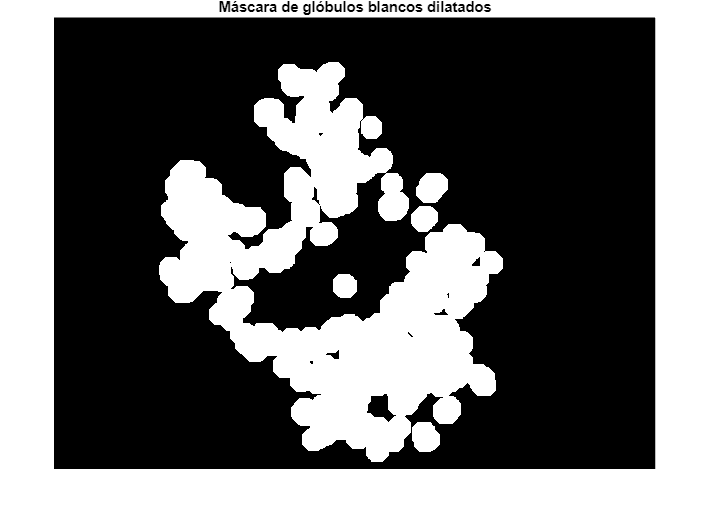


% Mostrar imagen con solo los glóbulos blancos segmentados
BW_RGB = repmat(mascara_GB, 1, 1, 3); 
solo_globulos = IPF;
solo_globulos(~BW_RGB) = 0; 

% Dilatación
mascara_GB = imdilate(mascara_GB, strel('disk', 70));
figure; imshow(mascara_GB); title('Máscara de glóbulos blancos dilatados');

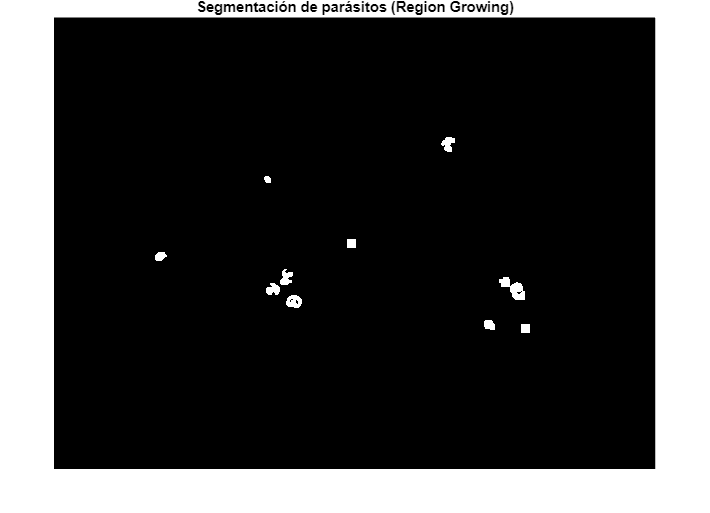


% Eliminar glóbulos blancos de la imagen de trabajo
I_masked = I_gray; I_masked(mascara_GB) = 0;
I_masked(~fov_mask) = 0;

% Segmentación de parásitos con Region Growing
I_filt = mat2gray(medfilt2(I_masked, [3 3]));
BW_dark = imbinarize(I_filt);
BW_dark = ~BW_dark;
BW_dark = bwareafilt(BW_dark, [50 Inf]);
stats_seed = regionprops(BW_dark, 'Centroid');
centroids = round(cat(1, stats_seed.Centroid));
mascara_parasitos = false(size(I_filt));

for i = 1:size(centroids, 1)
    y = centroids(i,2); x = centroids(i,1);
    if x > 1 && y > 1 && x <= size(I_filt,2) && y <= size(I_filt,1)
        region = regionGrowing(I_filt, [x, y], 0.1, 2000);  
        mascara_parasitos = mascara_parasitos | region;
    end
end

% Dilatación y limpieza
se = strel('disk', 10);
mascara_parasitos_DIL = imdilate(mascara_parasitos, se);
mascara_parasitos_ruido = mascara_parasitos_DIL & ~mascara_GB;

% Visualizar parásitos segmentados
figure; imshow(mascara_parasitos_ruido); title('Segmentación de parásitos (Region Growing)');

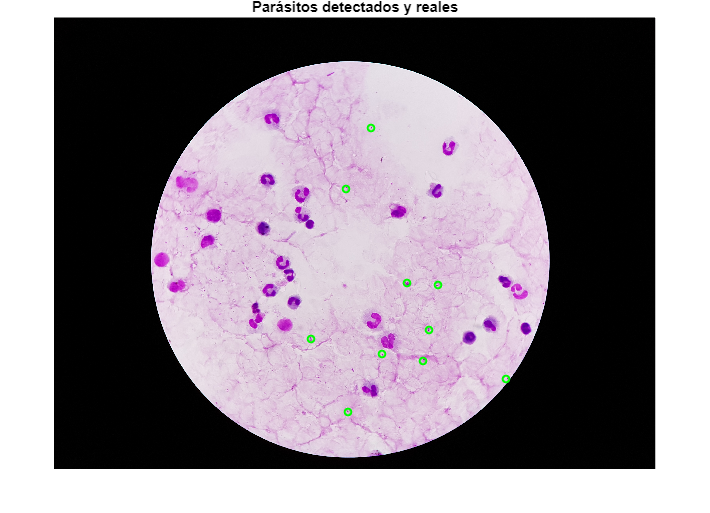


% Detección de círculos
[centros_parasitos, radios_parasitos] = imfindcircles(mascara_parasitos_ruido, [2 5], ...
    'Sensitivity', 0.92, 'EdgeThreshold', 1);

numDetectadosAuto = size(centros_parasitos, 1);
numParasitosReales = size(solo_parasitos, 1);
numTotalParasitos = numDetectadosAuto + numParasitosReales;

% Mostrar detecciones
figure; imshow(IPF); title('Parásitos detectados y reales'); hold on;
viscircles(centros_parasitos, radios_parasitos, 'EdgeColor', 'r');
plot(solo_parasitos{:,6}, solo_parasitos{:,7}, 'go', 'MarkerSize', 5, 'LineWidth', 1.5);
hold off;


fprintf('Parásitos detectados automáticamente: %d\n', numDetectadosAuto);

Parásitos detectados automáticamente: 0


fprintf('Parásitos reales anotados: %d\n', numParasitosReales);

Parásitos reales anotados: 10


fprintf('Total parásitos: %d\n', numTotalParasitos);

Total parásitos: 10




% Evaluación: comparación con reales
radio_extra = 20;
aciertos = 0;
for i = 1:size(solo_parasitos, 1)
    punto_real = [solo_parasitos{i,6}, solo_parasitos{i,7}];
    for j = 1:size(centros_parasitos, 1)
        centro_detectado = centros_parasitos(j,:);
        if norm(punto_real - centro_detectado) <= radios_parasitos(j) + radio_extra
            aciertos = aciertos + 1;
            break;
        end
    end
end
fprintf('Parásitos correctamente detectados: %d de %d reales\n', aciertos, size(solo_parasitos,1));

Parásitos correctamente detectados: 0 de 10 reales


fprintf('Falsos positivos: %d\n', size(centros_parasitos,1) - aciertos);

Falsos positivos: 0


fprintf('Falsos negativos: %d\n', size(solo_parasitos,1) - aciertos);

Falsos negativos: 10


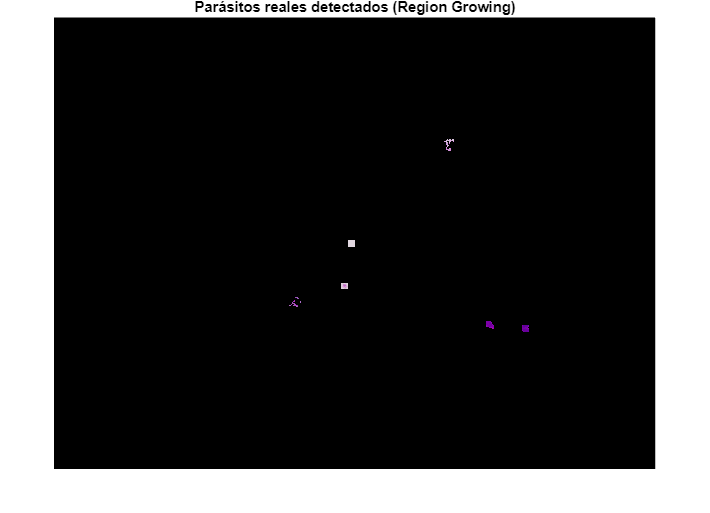


% Máscara solo parásitos reales detectados
props = regionprops(mascara_parasitos, 'Centroid', 'PixelIdxList');
x_real = solo_parasitos{:,6}; y_real = solo_parasitos{:,7};
indices_objetos = zeros(length(x_real), 1);
for i = 1:length(x_real)
    centroides = reshape([props.Centroid], 2, [])';
    distances = vecnorm(centroides - [x_real(i), y_real(i)], 2, 2);
    [~, idx] = min(distances);
    indices_objetos(i) = idx;
end

bw_parasitos_reales = false(size(mascara_parasitos));
for i = 1:length(indices_objetos)
    bw_parasitos_reales(props(indices_objetos(i)).PixelIdxList) = true;
end

% Visualización color
parasitos_color = zeros(size(IPF), 'like', IPF);
for c = 1:3
    temp = IPF(:,:,c);
    temp(~bw_parasitos_reales) = 0;
    parasitos_color(:,:,c) = temp;
end
figure; imshow(parasitos_color); title('Parásitos reales detectados (Region Growing)');

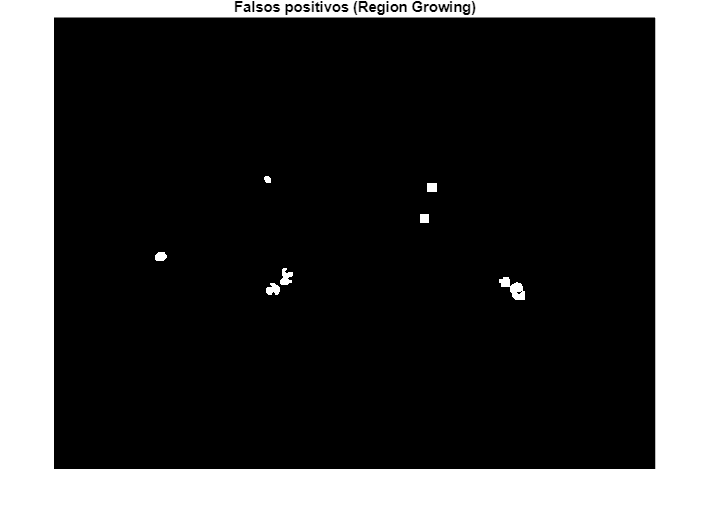


% Dilatar máscara
parasitos_gris = rgb2gray(parasitos_color);
bw_parasitos_color = parasitos_gris > 0;
bw_parasitos_dilatada = imdilate(bw_parasitos_color, strel('disk', 10));

% Falsos positivos
mascara_parasitos_FP = mascara_parasitos & ~bw_parasitos_dilatada;
mascara_parasitos_FP = imdilate(mascara_parasitos_FP, strel('disk', 10));

figure; imshow(mascara_parasitos_FP); title('Falsos positivos (Region Growing)');

function fov_mask  = segmentCellsStainBased(I)

    if size(I, 3) == 3
        I = rgb2gray(I);
    end
   
    level = graythresh(I);
    bw = imbinarize(I, level);
   
    if mean(I(bw)) < mean(I(~bw))
        bw = ~bw;
    end
   
    bw_clean = imopen(bw, strel('disk', 5));
    bw_clean = imclose(bw_clean, strel('disk', 5));
    bw_clean = imfill(bw_clean, 'holes');

    stats = regionprops(bw_clean, 'Area', 'Centroid', 'EquivDiameter');
   
    [~, idx] = max([stats.Area]);
    circle_centroid = stats(idx).Centroid;
    circle_radius = stats(idx).EquivDiameter / 2;
   
    adjusted_radius = max(circle_radius - 15, 0);
   
    [rows, cols] = size(bw_clean);
    [X, Y] = meshgrid(1:cols, 1:rows);

    fov_mask = (X - circle_centroid(1)).^2 + (Y - circle_centroid(2)).^2 <= adjusted_radius^2;

end

function salida = filtrar_por_tamano(imagen_binaria, umbral_max)
    componentes = bwlabel(imagen_binaria);
    stats = regionprops(componentes, 'Area');
    salida = ismember(componentes, find([stats.Area] <= umbral_max));
end

function region_mask = regionGrowing(img, seed_point, intensity_thresh, max_size)
    img = double(img);
    region_mask = false(size(img));
    visited = false(size(img));

    % Inicialización
    queue = seed_point;
    region_intensity_mean = img(seed_point(2), seed_point(1));
    region_size = 0;

    % 8 conectividad
    neighbors = [-1 -1; 0 -1; 1 -1; -1 0; 1 0; -1 1; 0 1; 1 1];

    while ~isempty(queue) && region_size < max_size
        current = queue(1,:); queue(1,:) = [];
        x = current(1); y = current(2);

        if x < 1 || y < 1 || x > size(img,2) || y > size(img,1)
            continue;
        end
        if visited(y,x)
            continue;
        end
        visited(y,x) = true;

        intensity = img(y,x);
        if abs(intensity - region_intensity_mean) <= intensity_thresh
            region_mask(y,x) = true;
            region_size = region_size + 1;
            region_intensity_mean = (region_intensity_mean*(region_size - 1) + intensity)/region_size;

            for k = 1:8
                xn = x + neighbors(k,1);
                yn = y + neighbors(k,2);
                if xn >= 1 && yn >= 1 && xn <= size(img,2) && yn <= size(img,1)
                    if ~visited(yn,xn)
                        queue(end+1,:) = [xn, yn];
                    end
                end
            end
        end
    end
end